# Line Integrals Solution

In your first integral calculus course, you evaluated many line integrals, but only along one path: from $x=a$ to $x=b$ along the $x$-axis! 

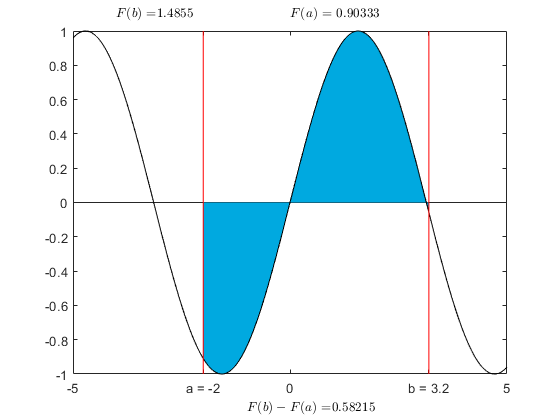

A line integral is a type of integral where a function is evaluated along a curve that can be more general than the $x$-axis. They are particularly useful in fields like physics and engineering, where they help understand and compute quantities like work done by a force field, electromagnetic induction, mass of a wire, or circulation and flux in vector fields. In this script, we will explore some of the calculations that can be done with line integrals over more varied paths. 

This live script is intended to be used with the code hidden. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code** using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free two-hour online tutorial that teaches the essentials of MATLAB.

  For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## **Glossary of Notation**

- $\vec{F}$ is a vector function

- $F$ is a scalar function

- $\mathbf{e}_x$ and $\mathbf{e}_r$ are unit vectors in the $x$ and $r$ directions, respectively

- $C$ is a path and $\vec{s}$ is a parameterization of the path

- $\frac{dx}{dt} = x^{\prime}(t)$ are both the derivative of $x$ with respect to $t$ 

## Background Discussion

The motivation for line integrals is to generalize the idea of a one-dimensional integral, as you are familiar with from [integral calculus](https://matlab.mathworks.com/open/github/v1?repo=MathWorks-Teaching-Resources/Calculus-Integrals&project=Integrals.prj&file=README.mlx), 


$$\int_a^b f(x)\; dx = F(b)-F(a),$$


where $F$ is an antiderivative of the scalar function $f$ to a definition that will apply to any one-dimensional path through space. We will cover two different types of line integrals. 

 **Type 1 (scalar function):** What does it mean to integrate a scalar function $F$ over a general path $C$? 

One example of Type 1 in thermodynamics is computing the work done along a closed cycle in Pressure-Volume space. 

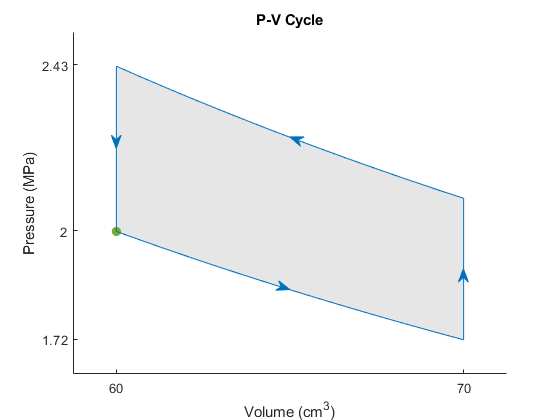

 **Type 2 (vector-valued function):** What does it mean to integrate a vector-valued function $\vec{F}$ over a general path $C$?

One example of Type 2 in electricity and magnetism is computing the work done to move a point charge from Point A to Point B along a particular path.

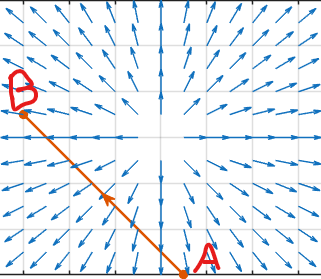

While the result of computing a line integral is always a scalar value, such as work, we need to determine how to create a scalar result from both Type 1 and Type 2 problems. 

## Definition of a Line Integral

Integrals measure the accumulation of some quantity. Let's consider how to define such a summation in the vector-valued function case. We can parameterize the curve $C$ with a vector-valued function $\vec{s}$. This allows us to compute the value of the vector field $\vec{F}$ at each point along $C$, which gives a unique vector denoted $\vec{F}(\vec{s})$ at each point. We will progress along the curve $C$ in an incremental fashion that we can denote by the vector-valued infinitesimal $d\vec{s}$. The amount of $\vec{F}(\vec{s})$ that is in the direction $d\vec{s}$ along the curve is calculated with the dot product $\vec{F}(\vec{s})\cdot d\vec{s}$. Thus, we can define the integral as:


$$\int_C \vec{F}(\vec{s})\cdot d\vec{s} = \lim_{||\Delta \vec{s}_i||\to 0}\sum_{i=1}^N \vec{F}(\vec{s}_i)\cdot \Delta \vec{s}_i$$


Let's take a curve $C$ in three dimensions. Then this integral can also be written in terms of $x$, $y$, and $z$. First, express $\vec{F}$ component-wise as $\vec{F}(\vec{s}) = M(x,y,z)\textbf{e}_x + N(x,y,z)\textbf{e}_y + P(x,y,z)\textbf{e}_z$, where $M, N,$ and $P$ are scalar functions. In this case, $\vec{s} = (x,y,z)$ and thus $d\vec{s} = dx\textbf{e}_x + dy\textbf{e}_y + dz \textbf{e}_z$ such that the line integral becomes

$\displaystyle \int_C \vec{F}(\vec{s})\cdot d\vec{s} = \int_C M(x,y,z)\; dx + \int_C N(x,y,z)\; dy + \int_C P(x,y,z)\; dz$.

This has reduced the line integral of a vector-valued function to the sum of several line integrals of scalar-valued functions. How can we compute this type of line integral? We have to relate the infinitesimal values $dx$, $dy$, and $dz$ to the infinitesimal along the path $C$, $ds$.

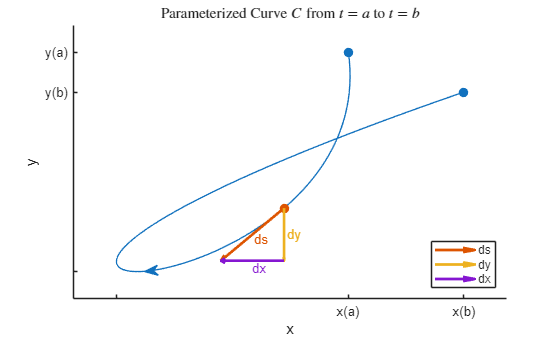

clearvars -except testCase fileToRun
tVals = linspace(-2,4,100);
xVals = tVals.^3-10*tVals;
yVals = (1-tVals).^2-0.3*tVals;
 
AnimateDS(xVals,yVals,StartingIndex=25,Animate=false);

If we consider the parameterization of $C$ expressed as $\vec{s}(t) = (x(t),y(t))$, then the triangular relationship gives us the suggestion:


$$\int_C F(x,y)\; ds  = \int_C F(x(t),y(t))\sqrt{\frac{dx}{dt}^2+\frac{dy}{dt}^2}\; dt = \int_C F(x(t),y(t))\left|\left| \frac{d\vec{s}(t)}{dt}\right|\right| \; dt$$


clearvars tVals xVals yVals

Does this relationship always exist as we traverse $C$? Is there always a right triangle created by $dx$, $dy$, and $ds$?

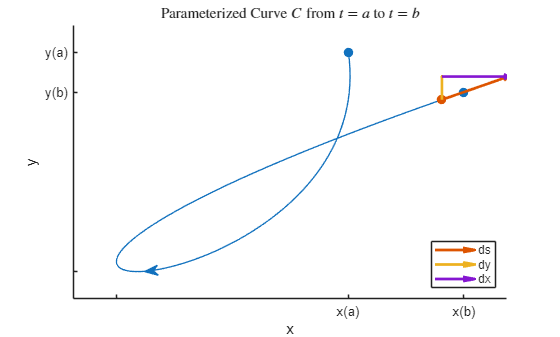

tVals = linspace(-2,4,100);
xVals = tVals.^3-10*tVals;
yVals = (1-tVals).^2-0.3*tVals;
 
AnimateDS(xVals,yVals);

The differential along the curve $ds$ changes length (or, equivalently, speed) as the starting point traverses the curve at a rate determined by the parameterization. Therefore, a scalar line integral is defined to be:

$\displaystyle \int_C F(\vec{s})\; ds = \lim_{||\Delta \vec{s}_i\,||\to 0} \sum_{i=1}^N F(\vec{s})\Delta \vec{s}_i = \int_C F(\vec{s}(t))\; ds = \int_a^b F(\vec{s}(t))||\vec{s}\prime(t)||\; dt$.

if $C$ is parameterized by $\vec{s}(t) = (x(t), y(t))$ for $a \leq t \leq b$.

clearvars tVals xVals yVals

## Independence of Parameterization

To compute any line integral, we will need to parameterize the curve over which the line integral is defined. Two parameterizations define the same curve if they trace the same set of points in space. They might trace the curve at different speeds or use different parameter values. However, since they trace the same points, the function $F$ evaluated along the curve is the same at corresponding locations. However, we are free to pick whichever parameterization is the most convenient for the calculation because the result is independent of parameterization. Consider two different parameterizations of $C$ given by $\vec{s_1}(t)$ from $t=a_1$ to $t=a_2$ and $\vec{s_2}(u)$ from $u=b_1$ to $u=b_2$. We know that $\vec{s_1}(a_1)= \vec{s_2}(b_1)$ and $\vec{s_1}(a_2) = \vec{s_2}(b_2)$, and in fact: 

$\displaystyle \int_{a_1}^{a_2}F(\vec{s_1}(t))||\vec{s_1}\prime(t)||\; dt = \int_{b_1}^{b_2}F(\vec{s_2}(u))||\vec{s_2}\prime(u)||\; du$.

This has to be true because we could choose all the same waypoints $\left(\vec{s}\!\right)_i=\left(\vec{s_1}\right)_i=\left(\vec{s_2}\right)_i$, and then $\Delta \vec{s}\!\!_i$ are all identical lengths and $F(\!\vec{s}\!_i)$ are all identical values. Fundamentally, when the step size for each integral changes, it is exactly counteracted by the change in speed, so $\left|\left|\frac{d\vec{s_1}}{dt}\right|\right|\; dt = \left|\left|\frac{d\vec{s_2}}{du}\right|\right|\;du$. 

### Notation for Line Integrals of Scalar Functions

The line integral of a scalar function along a curve $C$ is calculated using the same limit of Riemann sums as all the integrals studied in your first class in integral calculus, but now the calculation looks like


$$\int_C F(x,y)\; ds = \int_C F(x(t),y(t)) \; \left|\left|\frac{d\vec{s}}{dt}\right|\right|\; dt = \int_C F(x(t),y(t)) \sqrt{\left(\frac{dx}{dt}\right)^2 + \left(\frac{dy}{dt}\right)^2} \; dt.$$


### Notation for Line Integrals of Vector Fields

Computing a line integral over a vector field sounds like it might be more complicated, but in some ways it is a more straightforward calculation. The component of the vector field that is aligned with the curve at each point will contribute, and the perpendicular components will not. Therefore


$$\int_C \vec{F}(x,y) \cdot d\vec{s} = \int_C \vec{F}(x,y)\cdot\left(\frac{\partial s}{\partial x}\;dx,\frac{\partial s}{\partial y}\;dy\right) = \int_C \vec{F}(x(t),y(t))\cdot \left(\frac{dx}{dt},\frac{dy}{dt}\right) \; dt.$$


### Notation for Line Integrals Around Closed Loops

One common type of line integral involves integrating along a closed loop path. If we denote the vector field by $\vec{F}(x,y)$

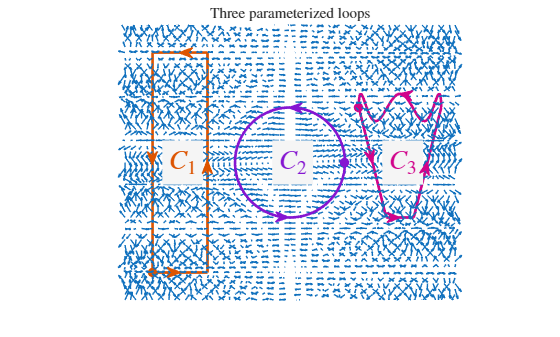

 
[X,Y] = meshgrid(-12:0.4:12,-10:0.4:10);
fig = figure;
BackColor = fig.Color;
q = quiver(X,Y,0.5*sin(X.*Y),X.*cos(Y)/16,"off");
xlim([-12 12])
ylim([-10 10])
axis equal off
hold on
PlotCycle("x","y",[-10 -6],[-8 -8],[-6 -6],[-8 8],[-6 -10],[8 8],[-10 -10],[8 -8], ...
    FillRegion=false,ResetLimits=false,SeriesIndex=2,LineWidth=2);
text(-9,0,"$C_1$",FontSize=20,FontWeight="bold",Interpreter="latex",SeriesIndex=2,BackgroundColor=BackColor)
Alpha = linspace(0,2*pi,100);
PlotCycle("x","y",4*cos(Alpha(1:50)),4*sin(Alpha(1:50)),4*cos(Alpha(50:end)), ...
    4*sin(Alpha(50:end)),FillRegion=false,ResetLimits=false,SeriesIndex=4,LineWidth=2);
PlotCycle("x","y",[5 7],[4 -4],[7 9],[-4 -4],[9 11],[-4 4],8+3*cos(Alpha(1:50)),[4+sin(Alpha(1:49)*5) 4],...
    TitleStr="Three parameterized loops",FillRegion=false,ResetLimits=false,SeriesIndex=7,LineWidth=2);
text(-1,0,"$C_2$",FontSize=20,FontWeight="bold",Interpreter="latex",SeriesIndex=4,BackgroundColor=BackColor)
text(7,0,"$C_3$",FontSize=20,FontWeight="bold",Interpreter="latex",SeriesIndex=7,BackgroundColor=BackColor)
hold off

the integral around a closed loop is denoted with a specific integral symbol, $\oint$, as in:

$\displaystyle \oint_{C_1} \vec{F}(x,y) \cdot d\vec{s}$     or     $\displaystyle \oint_{C_2} \vec{F}(x,y) \cdot d\vec{s}$     or     $\displaystyle \oint_{C_3} \vec{F}(x,y) \cdot d\vec{s}$.

 **Note:** The notation $\oint$ for an integral around a closed loop is commonly used for [contour integrals](https://www.mathworks.com/help/matlab/math/complex-line-integrals.html), which are line integrals around a closed loop in complex variable space. 

clear Alpha BackColor fig q X Y

## Computing Line Integrals

  **Try.** Choose a curve and a vector field and observe the resulting value.

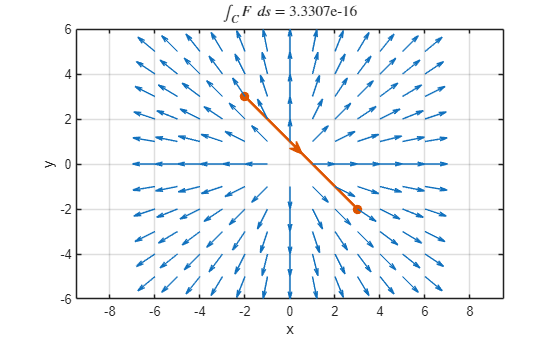

F = "radially outward"; C = "diagonal line";  
Pts = IdentifyCurve(C,F);
LineIntegralValue = CalculateResult(F,Pts);
PlotVectorField(1,VectorField=F,Dim="2D");
axis equal
hold on
PlotCycle("x","y",Pts(1:2),Pts(3:4),...
    FillRegion=false,ResetLimits=false,SeriesIndex=2,LineWidth=2,TitleStr="$\int_C F\; ds = $" + LineIntegralValue);
hold off


% displayFormula(['"The value of this integral is: "' "LineIntegralValue"])
function Val = CalculateResult(F,Pts)
dx = sign(Pts(2)-Pts(1));
dy = sign(Pts(4)-Pts(3));
if dx ~= 0
    XVec = Pts(1):sign(Pts(2)-Pts(1)):Pts(2);
else
    XVec = Pts(1);
end
if dy ~= 0
    YVec = Pts(3):sign(Pts(4)-Pts(3)):Pts(4);
else
    YVec = Pts(3);
end
if numel(XVec) ~= numel(YVec)
    if isscalar(YVec)
        YVec = YVec*ones(size(XVec));
        dir = "dx";
    elseif isscalar(XVec)
        XVec = XVec*ones(size(YVec));
        dir = "dy";
    else
        error("Incompatible dimensions of X and Y")
    end
else
    dir = "diag";
end
switch F
    case "x"
        MyIntegrand = [XVec; zeros(size(XVec))];
    case "negative y"
        MyIntegrand = [zeros(size(YVec)); -sign(YVec)];
    case "radially outward"
        RVec = sqrt(XVec.^2 + YVec.^2);
        RVec(RVec==0) = 1;
        SinTheta = YVec./RVec;
        CosTheta = XVec./RVec;
        MyIntegrand = [CosTheta; SinTheta];
end
switch dir
    case "dx"
        if F ~= "x"
        Val = sum(MyIntegrand(1,:))*(sign(Pts(2)-Pts(1)));
        else
        Val = (Pts(2)^2-Pts(1)^2)/2*(sign(Pts(2)-Pts(1)));
        end
    case "dy"
        Val = sum(MyIntegrand(2,:))*(sign(Pts(4)-Pts(3)));
    case "diag"
        if F ~= "x"
        Val = sum(MyIntegrand*sqrt(2)/2.*[sign(Pts(2)-Pts(1)); sign(Pts(4)-Pts(3))],"all");
        else
            Val = (Pts(2)^2-Pts(1)^2)*sqrt(2)/4*(sign(Pts(2)-Pts(1)));
        end
    otherwise
        error("Unset integration direction.")
end
end

function Pts = IdentifyCurve(C,F,opts)
arguments
    C 
    F 
    opts.Simple (1,1) logical = false 
end
EndPt = randi([-7 -4],1);
XShift = randi([-6 6],1);
if opts.Simple && F == "radially outward"
    YShift = XShift;
else
    YShift = randi([-6 6],1);
end
switch C
    case "??"
        StartX = 0;
        StopX = 6;
        StartY = 0; 
        StopY = 0; 
    case "horizontal line"
        StartX = abs(XShift);
        StopX = EndPt + abs(XShift);
        StartY = YShift; 
        StopY = YShift;         
    case "vertical line"
        StartX = XShift;
        StopX = XShift;
        StartY = abs(YShift); 
        StopY = EndPt+abs(YShift); 
    case "diagonal line"
        StartX = EndPt + abs(XShift);
        StopX = abs(XShift);
        StartY = EndPt + abs(YShift); 
        StopY = abs(YShift); 
    otherwise
        warning("Unexpected value for C: " + C)
end
Pts = [StartX,StopX,StartY,StopY];
if ~opts.Simple
FlipEnds = randi([0 1],2);
if FlipEnds(1)
    Pts = [Pts(2) Pts(1) Pts(3) Pts(4)];
end
if FlipEnds(2)
    Pts = [Pts(1) Pts(2) Pts(4) Pts(3)];
end
end
end

**Reflect.** What relationships between the vector fields and the curves result in positive, negative, or zero-valued line integrals? Can looking for symmetries help you simplify the problem?

### Qualitative Computation

 **Understanding Check.** Choose a curve and a vector field. Then determine whether the integral of that vector field along that curve is positive, negative, or zero. Repeat as often as you like to be confident that you understand the qualitative solution to the line integral of a vector field.

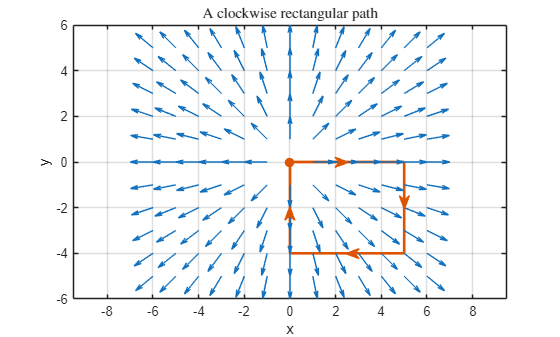

clear F C LineIntegralValue Pts
F = "radially outward"; C = "clockwise rectangle";  
step = 1;
PlotVectorField(step,VectorField=F,Dim="2D");
axis equal
DefineCurve(C)

SignOfIntegral = "zero"; 
CheckEx1(SignOfIntegral,C,F)

Yes, the integral of a radially outward field over this clockwise rectangle is visibly zero.
This does require observing that the radially outward field is conservative.


function CheckEx1(MyAns,C,F)
arguments
    MyAns (1,1) string {mustBeMember(MyAns,["??" "positive" "negative" "zero" "unclear"])}
    C (1,1) string {mustBeMember(C,["??" "circle" "positive circular arc" "negative circular arc" "clockwise rectangle" "counterclockwise rectangle" "sinusoid"])}    
    F (1,1) string {mustBeMember(F,["x" "negative y" "radially outward" "concentric circles" "eddies"])}
end
if C == "??"
    disp("You must select a curve to determine a line integral.")
    return
end

ClosedLoop = (C == "circle" || C == "clockwise rectangle" || C == "counterclockwise rectangle");
PositiveOrientation = (C == "circle" || C == "positive circular arc" || C == "counterclockwise rectangle");
Conservative = (F == "x" || F == "negative y" || F == "radially outward");
NegativeOrientation = (C == "clockwise rectangle" || C == "negative circular arc");

switch MyAns
    case "positive"
        if F == "x" && (C == "positive circular arc" || C == "sinusoid")
            CorrectMessage(C,F,MyAns)
        elseif F == "x" && C == "positive circular arc"
            CorrectMessage(C,F,MyAns)
        elseif F == "concentric circles" && PositiveOrientation
            CorrectMessage(C,F,MyAns)
        elseif F == "radially outward" && C == "sinusoid"
            CorrectMessage(C,F,MyAns)
        else
            IncorrectMessage(C,F,MyAns)
        end
    case "negative"
        if (F == "x" || F == "negative y") && C == "negative circular arc"
            CorrectMessage(C,F,MyAns)
        elseif F == "concentric circles" && NegativeOrientation
            CorrectMessage(C,F,MyAns)
        else 
            IncorrectMessage(C,F,MyAns)
        end
    case "zero"
        if Conservative && ClosedLoop
            CorrectMessage(C,F,MyAns)
            if F == "radially outward" && (C == "clockwise rectangle" || C == "counterclockwise rectangle")
                disp("This does require observing that the radially outward field is conservative.")
            end
        elseif (F == "negative y" || F == "concentric circles") && C == "sinusoid"
            CorrectMessage(C,F,MyAns)
        elseif (F == "radially outward") && (C == "negative circular arc" || C == "positive circular arc")
            CorrectMessage(C,F,MyAns)
            disp("The field is perpendicular to the path.")
        else
            IncorrectMessage(C,F,MyAns)
        end
    case "unclear"
        if F == "eddies"
            disp("Yes, it is unclear what the solution is from this plot.")
            disp("This vector field is rapidly changing and would require careful calculation.")
        elseif F == "radially outward" && (C == "clockwise rectangle" || C == "counterclockwise rectangle")
            disp("Fair, the sign might not be immediately visible.")
            disp("In fact, this vector field is ")
        else
            IncorrectMessage(C,F,MyAns)
        end
    case "??"
        disp("This is the default value. Please select positive, negative, zero, or unclear.")
    otherwise
        warning("Unexpected answer selction: " + MyAns)
end
end

function CorrectMessage(C,F,MyAns)
    if F == "x" || F == "eddies"
        ModStr = " an ";
    else
        ModStr = " a ";
    end
disp("Yes, the integral of" + ModStr + F + " field over this " + C + " is visibly " + MyAns + ".")
end

function IncorrectMessage(C,F,MyAns)
disp("No, it is not correct that the integral of a field that is " + F + " over this " + C + " is visibly " + MyAns + ".")
end

### Analytic Computation

To integrate a scalar function $F(x,y)$ along the path $C$, let's think about what this looks like in the basic integrals along the $x$-axis case:


$$\int_{x=a}^{x=b} F(x)\; dx.$$


This is a limit of Riemann sums of rectangles with height $F(x)$ and width $dx$. In this more general case, our height will still be the value of our function, but the width has to be an incremental step along our path. Let's denote that incremental step as $ds=\left|\left|\frac{d\vec{s}}{dt}\right|\right| \; dt= \sqrt{\left(\frac{dx}{dt}\right)^2 + \left(\frac{dy}{dt}\right)^2} dt$, which is the arc length element along our parameterized path. 

  **Try.** Use the button to randomly select a point and calculate its arc length along a parameterized piecewise path, $C(t) = \left(x(t),y(t)\right)$ with:

$x(t) = \cases{7t^2 & 0 \leq t < 1 \cr 7-7(t-1) & 1 \leq t < 2 \cr 14(t-2) & 2 \leq t \leq 3}$      and      $y(t) = \cases{t^3 & 0 \leq t < 1 \cr 1+8(t-1) & 1 \leq t < 2 \cr 9-\sin(t-2) & 2 \leq t \leq 3}$.     

Note that

 $\frac{dx}{dt} = \cases{14t & 0 < t < 1 \cr -7 & 1 < t < 2 \cr 14 & 2 < t < 3}$    and    $\frac{dy}{dt} = \cases{3t^2 & 0 < t < 1 \cr 8 & 1 < t < 2 \cr -\cos(t-2) & 2 < t < 3}$.

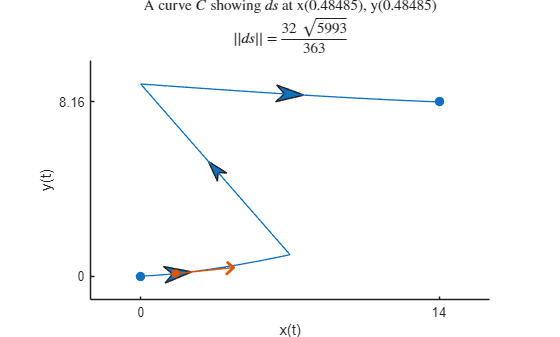

clearvars C F SignOfIntegral
 
if ~exist("PiecewisePath","var")
PiecewisePath = PlotPiecewisePath();
end

UpdatePiecewisePath(PiecewisePath)


function PathStruct = PlotPiecewisePath()
syms t
PathStruct.xFun = [t.^2 1-(t-1) 2.*(t-2)]*7;
PathStruct.yFun = [t.^3 1+8.*(t-1) 9-sin(t-2)];
assert(numel(PathStruct.xFun)==numel(PathStruct.yFun))
n = numel(PathStruct.xFun);
Steps = max(ceil(100/n),10);
xyVAll = cell(2*n,1);
for idx = 1:n
    tVals = linspace(idx-1,idx,Steps);
    xVals = matlabFunction(PathStruct.xFun(idx));
    yVals = matlabFunction(PathStruct.yFun(idx));
    xyVAll{2*idx-1,1} = xVals(tVals);
    xyVAll{2*idx,1} = yVals(tVals);
end
figure
syms dy dx dt
dxdy = str2sym("sqrt((dx/dt)^2+(dy/dt)^2)");
title("A curve $C$ showing $ds$ at x(" + 0 + "), y(" + 0 + ")")
subtitle("$||ds|| = " + latex(dxdy) + "$",Interpreter="latex")
PathStruct.ax = PlotCycle("x(t)","y(t)",xyVAll{:},TitleStr="",MyArrows=true);
PathStruct.s = scatter(PathStruct.ax,0,0,40,"filled",SeriesIndex=2);
PathStruct.ell = plot(PathStruct.ax,0,0,SeriesIndex=2);
PathStruct.arrow = plot(PathStruct.ax,0,0,SeriesIndex=2,LineWidth=2);
PathStruct.XY = xyVAll;
axis equal
%q = quiver(ax,0,0,0,0,SeriesIndex=2,LineWidth=2);
end

function UpdatePiecewisePath(PathStruct)
syms t
n = numel(PathStruct.xFun);
idx = randi(n,1);
Steps = max(ceil(100/n),10);
MyStep = randi(Steps,1);
tVals = linspace(idx-1,idx,Steps);
t0 = tVals(MyStep);
xF = PathStruct.xFun(idx);
yF = PathStruct.yFun(idx);
dx = diff(xF,t);
x0 = PathStruct.XY{2*idx-1}(MyStep);
y0 = PathStruct.XY{2*idx}(MyStep);

try 
    dx0 = subs(dx,t,t0);
catch
    dx0 = dx;
end
dy = diff(yF,t);
try
    dy0 = subs(dy,t,t0);
catch
    dy0 = dy;
end
dxdy = sqrt(dx0^2+dy0^2);
Scale = [(PathStruct.ax.Position(3)-PathStruct.ax.Position(1))/range(PathStruct.ax.XLim) (PathStruct.ax.Position(4)-PathStruct.ax.Position(2))/range(PathStruct.ax.YLim)];
PerpDir = double([-dy0 dx0]); 
Dir = double([dx0 dy0]/dxdy);
Scale = Scale/norm(Scale);
PerpDir = PerpDir/norm(PerpDir);

title(PathStruct.ax,"A curve $C$ showing $ds$ at x(" + t0 + "), y(" + t0 + ")")
subtitle(PathStruct.ax,"$||ds|| = " + latex(dxdy) + "$",Interpreter="latex")

PathStruct.s.XData = x0;
PathStruct.s.YData = y0;
dStep = double([dx0 dy0]);
tip = [x0 y0] + 2*dStep/5;
Shift = 0.3*PerpDir;
ArrowData = [tip-0.4*Dir-Shift; tip; tip-0.3*Dir+Shift];

PathStruct.ell.XData = [x0 tip(1)];
PathStruct.ell.YData = [y0 tip(2)];
PathStruct.arrow.XData = ArrowData(:,1);
PathStruct.arrow.YData = ArrowData(:,2);
pause(0)
end

Therefore, changing variables back to our parameterization gives:


$$\int_C F(x,y)\; ds = \int_C F(x(t),y(t)) \; \left|\left|\left(\frac{dx}{dt},\frac{dy}{dt}\right)\right|\right|\; dt = \int_C F(x(t),y(t)) \sqrt{\left(\frac{dx}{dt}\right)^2 + \left(\frac{dy}{dt}\right)^2} \; dt$$


When $C$ is composed of multiple components, the integral can be split into sums of the integral over each subcomponent:


$$\int_C F(x,y)\; ds = \int_{C_1}F(x,y)\; ds + \int_{C_2}F(x,y)\; ds + \cdots + \int_{C_n}F(x,y)\; ds$$


### Conservative Vector Fields

Recall that one formulation of the fundamental theorem of calculus states that if $\frac{dF}{dx} = f(x)$, then $\displaystyle \int_a^b f(x)\; dx = F(b)-F(a)$. If we are in a scenario where the integrand is the gradient of a scalar function, $\vec{F} = \nabla G = \frac{\partial G}{\partial x}\mathbf{e}_x+\frac{\partial G}{\partial y}\mathbf{e}_y$ , then the line integral can also be solved by the fundamental theorem of calculus. Let $\vec{s(t)} = (x(t),y(t))$ be a parameterization of $C$ from $t=a$ to $t=b$, then


$$\int_C \vec{F}\cdot d\vec{s} = \int_C \nabla G \cdot \left|\left|\frac{d\vec{s}}{dt}\right|\right|\; dt = \int_C \frac{dG(\vec{s})}{dt} \; dt = \int_C dG = G(\vec{s}(b))-G(\vec{s}(a)).$$


 **Note:** Remember the multivariate chain rule: With $G(x,y)$, $\frac{d}{dt}\left(G(x,y)\right) = \nabla G\cdot \left(\frac{dx}{dt},\frac{dy}{dt}\right) = \frac{\partial G}{\partial x}\frac{dx}{dt} + \frac{\partial G}{\partial y}\frac{dy}{dt}$.

A vector field where $\vec{F}=\nabla G$, for some scalar function $G$, is called ***conservative.*** This means that the results of line integrals are independent of the path chosen and only depend on the first and last point of the path. It also means that the integral of a conservative vector field around any closed loop must be zero. Conversely, if the integral of a vector field around any closed loop is not zero, the vector field is not conservative. 

 **Reflect.** Why does it follow that integrals of conservative vector fields around closed loops must be zero?

#### Identifying Conservative Vector Fields

In the 2D case, we know that $\vec{F}$ is conservative if there exists a $G$ with $\vec{F} = \nabla G$. To check for this, note the following annotated proof:

A similar result in 3D also shows that $\vec{F}$ is conservative if and only if

$\displaystyle \text{curl}(\vec{F}) = \left(\frac{\partial \vec{F}\!\!_z}{\partial y} - \frac{\partial \vec{F}\!\!_y}{\partial z}\right)\textbf{e}_x + \left(\frac{\partial \vec{F}\!\!_x}{\partial z} - \frac{\partial \vec{F}\!\!_z}{\partial x}\right)\textbf{e}_y + \left(\frac{\partial \vec{F}\!\!_y}{\partial x} - \frac{\partial \vec{F}\!\!_x}{\partial y}\right)\textbf{e}_z = 0$.

**Example:**

a) $\vec{F} = xy\mathbf{e}_x + x^2\mathbf{e}_y -z^2 \mathbf{e}_z$.                          

Compute: 


$$\text{curl}\vec{F} =  \left(\frac{\partial (-z^2)}{\partial y}-\frac{\partial (x^2)}{\partial z}\right)\mathbf{e}_x + \left(\frac{\partial (xy)}{\partial z}-\frac{\partial (-z^2)}{\partial x}\right)\mathbf{e}_y  + \left(\frac{\partial (x^2)}{\partial x}-\frac{\partial (xy)}{\partial y}\right)\mathbf{e}_z$$


 
$$=  \left(0-0\right)\mathbf{e}_x + \left(0-0\right)\mathbf{e}_y + \left(2x-x\right)\mathbf{e}_z$$


 $= x\mathbf{e}_z$.

This is not 0, so $\vec{F}$ is not conservative.

b) $\vec{F} = x^2\mathbf{e}_x + y^2\mathbf{e}_y$

Compute: $\text{curl}\vec{F} = \left(\frac{\partial y^2}{\partial x}-\frac{\partial x^2}{\partial y}\right)\mathbf{e}_z = (0-0)\mathbf{e}_z = 0$, so $\vec{F}$ is conservative. 

  **Pro-tip**. You can compute the curl of a symbolic vector field in MATLAB with the command [`curl(F,Basis)`](https://www.mathworks.com/help/symbolic/sym.curl.html)`.`

 **Exercise 2.** Which of the following vector fields are conservative? Justify your answers.

a) $\vec{F} = (x-3)\,\textbf{e}_y$

b) $\vec{F} = \sin(x)\,\textbf{e}_{x}-y^2\,\textbf{e}_y$

c) $\vec{F} = \frac{6}{r^3}\mathbf{e}_r$

d) $\vec{F} = 2\mathbf{e}_x -3\mathbf{e}_y + \mathbf{e}_z$

e) $\vec{F} = y\sin(x)\,\mathbf{e}_x - y\cos(x)\, \mathbf{e}_y$

**Solution:**

Reasoning for a)

In this case $F_x = 0$ and $F_y=x-3$ so $\frac{\partial F_x}{\partial y} = 0$ and $\frac{\partial F_y}{\partial x} = 1$. Therefore, the curl is not zero, and this vector field is not conservative.

Reasoning for b)

In this case $F_x = \sin(x)$ and $F_y = -y^2$, so $\frac{\partial F_x}{\partial y} = 0$ and $\frac{\partial F_y}{\partial x} = 0$. Therefore, $\text{curl(\vec{F}) = 0$ and this vector field is conservative. We can identify the scalar function by integrating the components of $\vec{F}$ and recognizing that they must be equal. Thus, $\displaystyle G = \int F_x\; dx = -\cos(x)+C_1(y)$ and $\displaystyle G=\int F_y\; dy = -\frac{y^3}{3}+C_2(x)$ and so $\displaystyle G = -\cos(x)-\frac{y^3}{3}$ is a scalar function such that $\nabla G = \vec{F}$.

Reasoning for c)

In this case $F_r = \frac{6}{r^3}$ and $F_{\theta} = 0$, so $\frac{\partial F_r}{\partial \theta} = 0$ and $\frac{\partial F_{\theta}}{\partial r} = 0$. Therefore, $\text{curl(\vec{F}) = 0$ and this vector field is conservative. We can identify the scalar function by integrating the components of $\vec{F}$ and recognizing that they must be equal. Thus, $\displaystyle G = \int F_r\; dr = -\frac{3}{r^2}+C_1(\theta)$ and $\displaystyle G=\int F_\theta\; d\theta = C_2(r)$ and so $\displaystyle G = -\frac{3}{r^2}$ is a scalar function such that $\nabla G = \vec{F}$.

Reasoning for d)

In this case $F_x = 2$, $F_y = -3$, and $F_z=1$, so all partial derivatives with respect to any variables are 0. Therefore, $\text{curl(\vec{F}) = 0$ and this vector field is conservative. We can identify the scalar function by integrating the components of $\vec{F}$ and recognizing that they must be equal. Thus, $\displaystyle G = \int F_x\; dx = 2x+C_1(y,z)$ and $\displaystyle G=\int F_y\; dy = -3y+C_2(x,z)$, and $\displaystyle \int F_z\l dz = z+C_3(x,y)$, so $\displaystyle G = 2x-3y+z$ is a scalar function such that $\nabla G = \vec{F}$.

Reasoning for e)

In this case $F_x = y\sin(x)$ and $F_y=-y\cos(x)$ so $\frac{\partial F_x}{\partial y} = \sin(x)$ and $\frac{\partial F_y}{\partial x} = y\sin(x)$. Therefore, $\text{curl}(\vec{F}) = (y-1)\sin(x) \textbf{e}_z$ is not zero, and this vector field is not conservative.

 
%        a), b), c), d), e)
CheckEx2(true,false,false,false,true)

You are correct. Options b), c), and d) are conservative while a) and e) are not conservative.


$$\mathrm{a)}\left(\mathrm{curl}\left(\vec{F}\right)=e_{z}\right)\neq 0\mathrm{so}\vec{F}\mathrm{is not conservative.}$$

$$\mathrm{b)}G=-\cos\left(x\right)-\frac{y^{3}}{3}\mathrm{so}\vec{F}\mathrm{is conservative.}$$

$$\mathrm{c)}G=\frac{-3}{r^{2}}\mathrm{so}\vec{F}\mathrm{is conservative.}$$

$$\mathrm{d)}G=2\,x-3\,y+zs\vec{F}\mathrm{is conservative.}$$

$$\mathrm{e)}\left(\mathrm{curl}\left(\vec{F}\right)=\left(y-1\right)\,\sin\left(x\right)\,e_{z}\right)\neq 0\mathrm{so}\vec{F}\mathrm{is not conservative.}$$

### Practice Computing Line Integrals

 **Exercise 3.** 

clear F x y
F = "x"; C = "diagonal line";  
Pts = IdentifyCurve(C,F,Simple=true);
StateProblem(F,Pts)

$$\mathrm{The curve C is a straight line from (}-2,-3\mathrm{) to (}2,1\mathrm{) and}\vec{F}=x\,e_{x}.$$

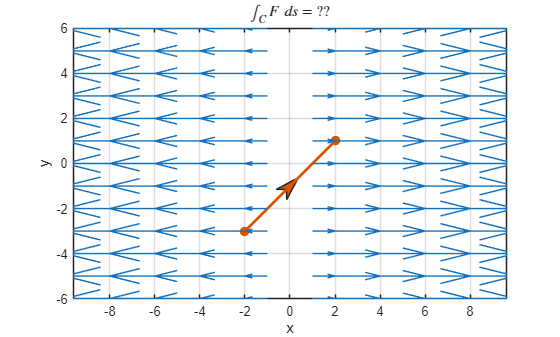

function StateProblem(Field,Pts)
x1 = Pts(1);
x2 = Pts(2);
y1 = Pts(3);
y2 = Pts(4);
str = ['"The curve C is a straight line from ("' "x1" '","' "y1" '") to ("' "x2" '","' "y2" '") and "'];

syms F_vec x r
syms e_x [2 1] matrix 
syms e_y [2 1] matrix
syms e_r [2 1] matrix
switch Field
    case "x"
        displayFormula([str "F_vec==x*e_x" '"."'])            
    case "negative y"
        displayFormula([str "F_vec==-sign(y)*e_y" '"."'])
    case "radially outward"
        displayFormula([str "F_vec==1*e_r" '" or, equivalently, "' "F_vec==x/sqrt(x^2+y^2)*e_x + y/sqrt(x^2+y^2)*e_y" '"."'])
    otherwise
        error("Unexpected field value: " + Field)
end
end

PlotVectorField(1,VectorField=F,Dim="2D");
axis equal
hold on
PlotCycle("x","y",Pts(1:2),Pts(3:4),...
    FillRegion=false,ResetLimits=false,SeriesIndex=2,LineWidth=2,TitleStr="$\int_C F\; ds = ??$",MyArrows=true);
hold off

**Solution:**

 
try
SolutionExercise3(F,Pts,C,PrintSolution=true);
catch 
    error("You must generate a problem for Exercise 3 before solving it.")
end

The curve is a straight diagonal line.


$$\mathrm{C can be parameterized as}s\left(t\right)\mathrm{= (}x\left(t\right),y\left(t\right)\mathrm{) with}x\left(t\right)=4\,t-2\mathrm{and}y\left(t\right)=4\,t-3\mathrm{for}\left(0\leq t\right)\leq 1.$$

$$\mathrm{This means that}\frac{\mathrm{ds}}{\mathrm{dt}}\mathrm{= (}4,4\mathrm{).}$$

$$\mathrm{Note that in this case, the field can be parameterized as}\vec{F}=\left(4\,t-2\right)\,e_{x}.$$

$$\mathrm{So the problem becomes:}$$

$$\int_{0}^{1}\left(16\,t-8\right)\mathrm{d}t=0$$

clear F C Pts

 **Exercise 4.** Compute the following integrals. You can work on paper or in the Solution space given to document your computation.

**a)** $\displaystyle \int_C (x-3)\,\textbf{e}_y \cdot ds$ where $C$ is the curve $y=x^2$ from $x=0$ to $x=2$

**Solution**


$$\int_0^2 (x-3)\mathbf{e}_y \cdot (\mathbf{e}_x+2x\mathbf{e}_y)\; dx = \int_0^2 2x^2-6x\; dx = \left.\frac{2}{3}x^3-3x^2\right|_0^2 = \frac{16}{3}-12 = -\frac{20}{3}$$


Ex4SolnA = double(-20/3); 
CheckEx4(Ex4SolnA,"a")

This answer is correct.


**b)** $\vec{F} = \sin(x)\,\textbf{e}_{x}-y^2\,\textbf{e}_y$ where $C$ is the curve $y=\sin(x)\cos(x)-\frac{2x}{\pi}$ from $x=\frac{\pi}{2}$ to $x=\frac{3\pi}{2}$.

**Solution**

Note that $\vec{F}$ is conservative with $G = -\cos(x)-\frac{y^3}{3}$ and the initial point is $\left(\frac{\pi}{2},-1\right)$ while the final point is $\left(\frac{3\pi}{2},-3\right)$. Thus, 


$$\displaystyle \int_C \vec{F}\cdot ds = \left(-\cos\left(\frac{3\pi}{2}\right)-\frac{(-27)}{3}\right) - \left(-\cos\left(\frac{\pi}{2}\right)-\frac{(-1)}{3}\right) = \frac{26}{3}$$


Ex4SolnB = double(26/3); 
CheckEx4(Ex4SolnB,"b")

This answer is correct.


c) $\displaystyle \oint_C 2\mathbf{e}_x -3\mathbf{e}_y + \mathbf{e}_z\cdot d\mathbf{s}$ where $C$ is the closed loop shown below.

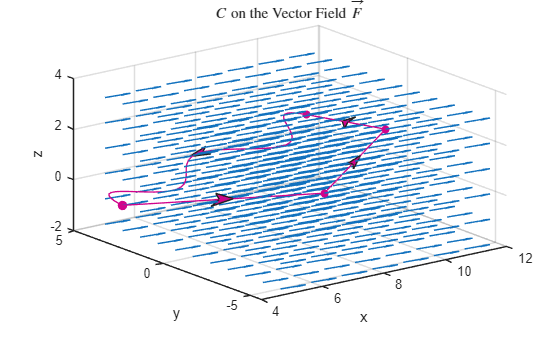

 
[X,Y,Z] = meshgrid(5:11,-5:5,-2:3);
figure
quiver3(X,Y,Z,2*ones(size(Z)),-3*ones(size(Z)),ones(size(Z)))
Alpha = linspace(0,2*pi,100);
hold on
ax = PlotCycle3("x","y","z",[5 7],[4 -4],[-1 1],[7 9],[-4 -4],[1 3],[9 11],[-4 4],[3 1],8+3*cos(Alpha(1:50)),[4+sin(Alpha(1:49)*5) 4],linspace(1,-1,50),...
    TitleStr="$C$ on the Vector Field $\vec{F}$",FillRegion=false,ResetLimits=false,SeriesIndex=7);
scatter3([7 9 11],[-4 -4 4],[1 3 1],"filled",SeriesIndex=7)
hold off

**Solution**

This vector field $\vec{F} = 2\mathbf{e}_x-2\mathbf{e}_y + \mathbf{e}_z$ is conservative, and the loop $C$ is closed. Therefore, the line integral of $\vec{F}$ over $C$ has to be $0$.

Ex4SolnC = double(0); 
CheckEx4(Ex4SolnC,"c")

This answer is correct.


**Solution**

d) $\displaystyle \int_C \left(y\sin(x)\,\mathbf{e}_x - y\cos(x)\, \mathbf{e}_y\right)\cdot d\mathbf{s}$ if $C$ is a straight line from $x=0$ to $x=\pi$ with $y=1$ and then at straight line from $y=1$ to $y=0$ with $x=\pi$.

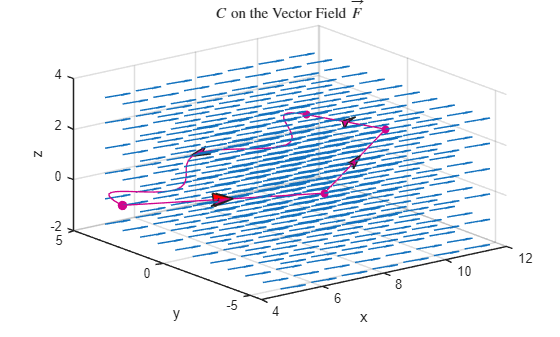

 
[X,Y,Z] = meshgrid(5:11,-5:5,-2:3);
figure
quiver3(X,Y,Z,2*ones(size(Z)),-3*ones(size(Z)),ones(size(Z)))
Alpha = linspace(0,2*pi,100);
hold on
PlotCycle3("x","y","z",[5 7],[4 -4],[-1 1],[7 9],[-4 -4],[1 3],[9 11],[-4 4],[3 1],8+3*cos(Alpha(1:50)),[4+sin(Alpha(1:49)*5) 4],linspace(1,-1,50),...
    TitleStr="$C$ on the Vector Field $\vec{F}$",FillRegion=false,ResetLimits=false,SeriesIndex=7);
pt1 = [5 4 -1];
pt2 = [7 -4 1];
dir = pt2-pt1;
tip = pt1 + 0.55*dir;
tail = pt1 + 0.45*dir;
perpdir = [0 dir(3) -dir(2)];
perpdir = perpdir/norm(perpdir);
tail1 = tail + 0.03*norm(dir)*perpdir;
tail2 = tail - 0.03*norm(dir)*perpdir;
arrowhead = [tail1; tip; tail2; tail1];
fill3(arrowhead(:,1),arrowhead(:,2),arrowhead(:,3),"r",SeriesIndex=7)
scatter3([7 9 11],[-4 -4 4],[1 3 1],"filled",SeriesIndex=7)
hold off

**Solution**


$$\int_{0}^{\pi} (\sin(x)\mathbf{e}_x-\cos(x)\mathbf{e}_y)\cdot\mathbf{e}_x\; dx + \int_1^0 (y\sin(\pi)\mathbf{e}_x-y\cos(\pi)\mathbf{e}_y)\cdot\mathbf{e}_y \; dy = \int_{0}^{\pi} \sin(x)\; dx + \int_1^0y\; dy $$


 
$$= \left.\left.\frac{y^2}{2}\right|_1^0-\cos(x)\right|_{0}^{\pi}  $$


 
$$=\left(0-\frac{1}{2}\right)-((-1)-1) = \frac{3}{2}$$


Ex4SolnD = double(1.5); 
CheckEx4(Ex4SolnD,"d")

This answer is correct.


e) $\displaystyle \int_C \left(y\sin(x)\,\mathbf{e}_x - y\cos(x)\, \mathbf{e}_y\right)\cdot d\mathbf{s}$ if $C$ is a closed loop consisting of straight lines from $x=0$ to $x=\pi$ with $y=1$ and then at straight line from $y=1$ to $y=0$ with $x=\pi$, and then a straight line from $x=\pi$ to $x=0$ with $y=0$, and a straight line from $y=0$ to $y=1$ with $x=0$.

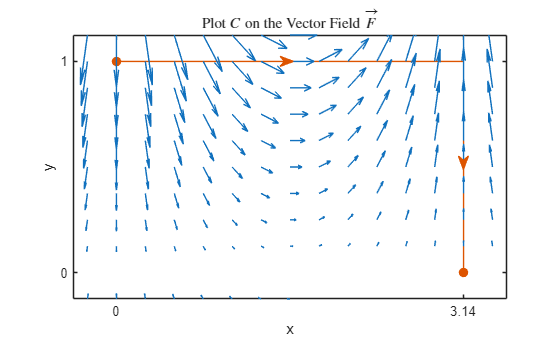

 
figure
[X,Y] = meshgrid(linspace(-pi/4,5*pi/4,19),-0.125:0.125:1.125);
quiver(X,Y,Y.*sin(X),-Y.*cos(X))
hold on
PlotCycle("x","y",[0 pi],[1 1],[pi pi],[1 0],ResetLimits=true,SeriesIndex=2,TitleStr="Plot $C$ on the Vector Field $\vec{F}$");
hold off

**Solution**


$$\int_{0}^{\pi} (\sin(x)\mathbf{e}_x-\cos(x)\mathbf{e}_y)\cdot\mathbf{e}_x\; dx + \int_1^0 (y\sin(\pi)\mathbf{e}_x-y\cos(\pi)\mathbf{e}_y)\cdot\mathbf{e}_y \; dy = \int_{0}^{\pi} \sin(x)\; dx + \int_1^0y\; dy $$



$$\int_{\pi}^{0}0\mathbf{e}_x-0\mathbf{e}_y \; dx + \int_0^1 y\sin(0)\mathbf{e}_x-y\cos(0)\mathbf{e}_y\; dy = \int_0^1-y\; dy $$


Adding all the path integrals, we have

 
$$\int_C \vec{F}\cdot d\vec{s} = 2\int_1^0 y\; dy + \int_0^{\pi} \sin(x)\; dx$$


 
$$= \left.2\left(\left.\frac{y^2}{2}\right|_1^0\right) + -\cos(x) \right|_0^{\pi}$$


 
$$=2\left(0-\frac{1}{2}\right)-((-1)-1) = 1$$


Ex4SolnE = double(1.5); 
CheckEx4(Ex4SolnE,"e")

The value 1.5 is not correct.
Please try again.


clearvars Ex4SolnA Ex4SolnB Ex4SolnC Ex4SolnD Ex4SolnE X Y Z

## Green's Theorem

Let $L$ and $M$ be functions of $x$ and $y$, and let $C$ be a positively (counterclockwise) oriented curve. If $L$ and $M$ have continuous partial derivatives and $C$ is piecewise smooth, then


$$\oint_C L\; dx + M\; dy = \int\!\!\!\!\!\!\int \left(\frac{\partial M}{\partial x} - \frac{\partial L}{\partial y}\right) \; dA$$


 **Reflect.** What are you calculating if $M=x$? Or if $L=3-y$?

### Applications of Green's Theorem

Green's Theorem can move calculations from one dimension to another. For instance, if we consider functions $L$ and $M$ such that $\left(\frac{\partial M}{\partial x} - \frac{\partial L}{\partial y}\right)  = 1$, then the right-hand side of Green's Theorem is $\displaystyle \int\!\!\!\!\!\!\int 1 \; dA = \text{Area}$. This means that for shapes where the boundary is easier to work with, we can compute the area by only doing an integral around the boundary. 

#### Calculating Area

We can calculate the area of a complex shape in a variety of ways by using Green's Theorem. Consider calculating the area of an irregular star:

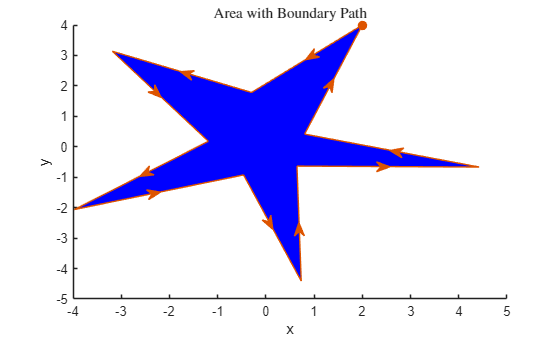

 
ControlPoints = GenerateStar();
PlotStar(ControlPoints)

function PlotStar(ControlPoints)
clf
if ControlPoints(1,1) ~= ControlPoints(1,end) || ControlPoints(2,1) ~= ControlPoints(2,end)
    NumEdges = numel(ControlPoints(1,:));
    ControlPoints = [ControlPoints ControlPoints(:,1)];
else
    NumEdges = numel(ControlPoints(1,:))-1;
end

StarEdges = cell([1 2*NumEdges]);
for edge = 1:NumEdges
    StarEdges{2*edge-1} = ControlPoints(1,edge:edge+1);
    StarEdges{2*edge} = ControlPoints(2,edge:edge+1);
end

PlotCycle("x","y",StarEdges{:},TitleStr="Area with Boundary Path",SeriesIndex=2, ...
    ResetLimits=false,MyArrows=false,FillColor="b");
end

By computing 


$$\displaystyle \oint_{\partial \text{Star}} -y\; dx = \int\!\!\!\!\!\!\int_{\text{Star}} 1\; dA = \text{Area},$$


and because each edge is straight, this becomes a series of 10 integrals

ComputeAreaSolution(ControlPoints);

$$\mathrm{Edge}1:\int_{2.0}^{-0.2965}\left(-0.9647\,x-2.0706\right)\mathrm{d}x=6.6422$$

$$\mathrm{Edge}2:\int_{-0.2965}^{-3.1862}\left(0.4684\,x-1.6456194\right)\mathrm{d}x=7.1125$$

$$\mathrm{Edge}3:\int_{-3.1862}^{-1.1926}\left(1.484\,x+1.5901208\right)\mathrm{d}x=-3.3072$$

$$\mathrm{Edge}4:\int_{-1.1926}^{-3.9692}\left(-0.8068\,x-1.14178968\right)\mathrm{d}x=-2.6112$$

$$\mathrm{Edge}5:\int_{-3.9692}^{-0.4623}\left(0.77487612-0.3239\,x\right)\mathrm{d}x=5.2342$$

$$\mathrm{Edge}6:\int_{-0.4623}^{0.7331}\left(2.917\,x+2.2731291\right)\mathrm{d}x=3.1895$$

$$\mathrm{Edge}7:\int_{0.7331}^{0.6444}\left(42.5876\,x-26.80936956\right)\mathrm{d}x=-0.2238$$

$$\mathrm{Edge}8:\int_{0.6444}^{4.4223}\left(0.0083\,x+0.62935148\right)\mathrm{d}x=2.457$$

$$\mathrm{Edge}9:\int_{4.4223}^{0.8028}\left(0.2992\,x-0.65715216\right)\mathrm{d}x=-0.4512$$

$$\mathrm{Edge}10:\int_{0.8028}^{2.0}\left(1.9860804-2.993\,x\right)\mathrm{d}x=-2.6439$$

$$\mathrm{The area of the star is the sum total:}15.3981$$


function Total = ComputeAreaSolution(ControlPoints,opts)
arguments
    ControlPoints (2,:) double
    opts.ShowSolution (1,1) logical = true
end
if ControlPoints(1,1) ~= ControlPoints(1,end) || ControlPoints(2,1) ~= ControlPoints(2,end)
    NumEdges = numel(ControlPoints(1,:));
    ControlPoints = [ControlPoints ControlPoints(:,1)];
else
    NumEdges = numel(ControlPoints(1,:))-1;
end
Total = 0;
syms x y
for edge = 1:NumEdges
    if ControlPoints(1,edge+1)==ControlPoints(1,edge)
        EdgeIntegrand = -y;
        OutVal = 0;
        if opts.ShowSolution
        OutValPrint = 0;
        end
    else
        m = (ControlPoints(2,edge+1)-ControlPoints(2,edge))/(ControlPoints(1,edge+1)-ControlPoints(1,edge));
        EdgeIntegrand = -round(vpa(m),4)*(x-round(vpa(ControlPoints(1,edge),4),4))-round(vpa(ControlPoints(2,edge),4),4);
        OutVal = int(-m*(x-ControlPoints(1,edge))-ControlPoints(2,edge),x,ControlPoints(1,edge),ControlPoints(1,edge+1));
        if opts.ShowSolution
        OutValPrint = round(vpa(OutVal),4);
        end
    end
    Total = Total + OutVal;
    if opts.ShowSolution
    a = round(vpa(ControlPoints(1,edge)),4);
    b = round(vpa(ControlPoints(1,edge+1)),4);
    displayFormula(['"Edge "' "edge" '":"' "int(EdgeIntegrand,x,a,b)==OutValPrint"])
    end
end

TotalPrint = round(vpa(Total),4);
if opts.ShowSolution
displayFormula(['"The area of the star is the sum total: "' "TotalPrint"])
end
end

clearvars ControlPoints

 **Exercise 5.**

Compute the area of the figure shown below:

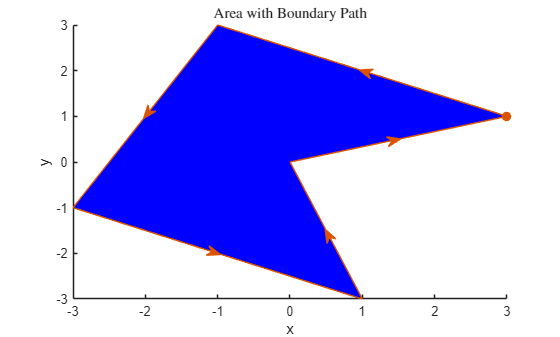

 
CP = round(GenerateStar(Points=4));
CPsmall = CP(:,1:2:end);
if mod(numel(CPsmall),4)~=2
    CPsmall = CPsmall(:,1:end-1);
end
PlotStar(CPsmall)

**Solution:**

 
CorrectSoln = ComputeAreaSolution(CPsmall,ShowSolution=true)

$$\mathrm{Edge}1:\int_{3.0}^{-1.0}\left(0.5\,x-2.5\right)\mathrm{d}x=8.0$$

$$\mathrm{Edge}2:\int_{-1.0}^{-3.0}\left(-2.0\,x-5.0\right)\mathrm{d}x=2.0$$

$$\mathrm{Edge}3:\int_{-3.0}^{1.0}\left(0.5\,x+2.5\right)\mathrm{d}x=8.0$$

$$\mathrm{Edge}4:\int_{1.0}^{0}3.0\,x\mathrm{d}x=-1.5$$

$$\mathrm{Edge}5:\int_{0}^{3.0}\left(-0.3333\,x\right)\mathrm{d}x=-1.5$$

$$\mathrm{The area of the star is the sum total:}15.0$$

$$CorrectSoln = 15$$

#### Application: Induction cooktops

Let $\vec{E}$ be an electric field and $\vec{B}$ the associated magnetic field. Faraday's law states that for any stationary closed spatial loop $C=\partial S$ for a surface $S$, the electromotive force is the rate of change of the magnetic flux, $\Phi_B$, through $S$ is given by:

$-\displaystyle \frac{d\Phi_B}{dt} = -\frac{d}{dt}\int\!\!\!\!\!\!\int_S \vec{B}\cdot d\vec{A} =  \int_C \vec{E}\cdot d\vec{s}$.

An induction cooktop contains a coiled wire beneath the surface. When alternating current flows through the coil, $C$, it generates a changing magnetic field $\vec{B}$ perpendicular to the cooktop. When a ferromagnetic pan, such as a cast iron skillet, is placed on the cooktop, the magnetic field generates an eddy current in the pan. The resistance of the metal to the eddy current generates heat. This is safer and more efficient than earlier electric stoves because the heat is generated directly in the cooking surface rather than on the stove top. 

#### **Application: Thermodynamic work**

Consider a frictionless piston-cylinder device containing 0.8 cubic meters of air at 110 kPa and 75C. The piston compresses the air in the cylinder isothermally until it reaches a volume of 0.5 cubic meters. Assume that the air in this scenario can be treated as an ideal gas satisfying the ideal gas law:


$$PV = nR_uT,$$


and also that the expansion occurs in quasi-equilibrium, so

$PV = P_0V_0 = (0.8)\cdot(110) \text{ kJ} = 88 \text{ kJ}$.

Therefore, we can use the relationship $P = \frac{88}{V}$ to compute pressure values in $\text{kPa}$ at known volumes.

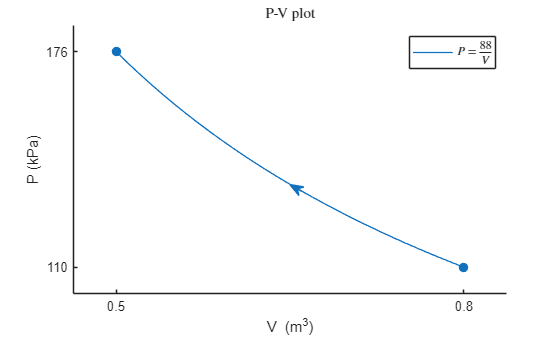

 
vValues = 0.8:-0.01:0.5;
pValues = 88./vValues;
clf
PlotCycle("V (m^3)","P (kPa)",vValues,pValues);
legend(["" "$P = \frac{88}{V}$"],Interpreter="latex")

The work done by the piston-cylinder system is

$\displaystyle \text{Work} = \int_{0.8}^{0.5}\frac{88}{V}\; dV$.

 
% Symbolically calculate the integral in kJ
syms V
W = int(88/V,V,0.8,0.5);
% Convert the solution to a decimal value in kJ
Work = round(vpa(W),4);
displayFormula(['"Work = "' "W" '" which is approximately "' "Work" '" kJ."'])

$$\mathrm{Work =}-88\,\log\left(\frac{8}{5}\right)\mathrm{which is approximately}-41.3603\mathrm{kJ.}$$

displayFormula('"Because the work is negative, this means that we must put energy into the system to compress the cylinder."')

$$\mathrm{Because the work is negative, this means that we must put energy into the system to compress the cylinder.}$$

### **Reflect**.

- Can you sketch a P-V plot with a cycle that generates positive work? 

function AnimateDS(xVals,yVals,opts)
arguments
    xVals 
    yVals 
    opts.StartingIndex = 1 
    opts.Animate (1,1) logical = true
end
clf
ax = PlotCycle("x","y",xVals,yVals,TitleStr="Parameterized Curve $C$ from $t=a$ to $t=b$");
ax.XTickLabel = ["" "x(a)" "x(b)"];
ax.YTickLabel = ["" "y(b)" "y(a)"];
x0 = xVals(opts.StartingIndex);
y0 = yVals(opts.StartingIndex);
dx0 = xVals(2:end)-xVals(1:end-1);
dy0 = yVals(2:end)-yVals(1:end-1);
scaleFactor = 7./sqrt(dx0.^2+dy0.^2);
dxInit = dx0(opts.StartingIndex)*scaleFactor(opts.StartingIndex);
dyInit = dy0(opts.StartingIndex)*scaleFactor(opts.StartingIndex);
pt = scatter(ax,x0,y0,50,"filled",SeriesIndex=2);
ds = quiver(ax,x0,y0,dxInit,dyInit,SeriesIndex=2,AutoScale="off",LineWidth=2);
dy = quiver(ax,x0,y0,0,dyInit,SeriesIndex=3,AutoScale="off",LineWidth=2);
dx = quiver(ax,x0,y0+dyInit,dxInit,0,SeriesIndex=4,AutoScale="off",LineWidth=2);
legend(["" "" "" "ds" "dy" "dx"],Location="best")
if opts.Animate
for idx = 2:99
    pt.XData = xVals(idx);
    pt.YData = yVals(idx);
    ds.XData = xVals(idx);
    ds.YData = yVals(idx);
    ds.UData = dx0(idx)*scaleFactor(idx);
    ds.VData = dy0(idx)*scaleFactor(idx);
    dy.XData = xVals(idx); 
    dy.YData = yVals(idx);
    dy.VData = dy0(idx)*scaleFactor(idx);
    dx.XData = xVals(idx);
    dx.YData = yVals(idx)+dy0(idx)*scaleFactor(idx);
    dx.UData = dx0(idx)*scaleFactor(idx);
    pause(0)
end
else
    text(x0+0.5*dxInit+0.2,y0+0.5*dyInit-0.2,"ds",SeriesIndex=2)
text(ax,x0+0.5*dxInit,y0+dyInit-0.35,"dx",SeriesIndex=4)
text(ax,x0+0.35,y0+0.5*dyInit,"dy",SeriesIndex=3)
end
end

function PlotVectorField(step,opts)
arguments
    step (1,1) double {mustBePositive} = 0.5
    opts.VectorField (1,:) string = ""
    opts.Dim (1,1) string {mustBeMember(opts.Dim,["2D" "3D"])} = "2D"
    opts.Coords (1,1) string = "Cartesian"
end
figure
% Create a grid of points for the vector field
if opts.Dim == "2D"
    [x, y] = meshgrid(-6:step:6, -6:step:6);
else
    [x, y, z] = meshgrid(-6:step:6, -6:step:6, -6:step:6);
    % Calculate the radial distance from the origin
    r = sqrt(x.^2 + y.^2 + z.^2);
    cIdx = ceil(r)+1;
end

% Define a grid for the vector field with the
% mesh size (re)-defined by the learner
switch opts.VectorField
    case "concentric circles"
        % Define a tangent vector field to the radial field
        u = -y; % velocity in the x-direction
        v = x;  % velocity in the y-direction
        if opts.Dim == "3D"
            w = sign(z);
            titleStr = "A circulating vector field";
        else
            titleStr = "A vector field in the $\theta$-direction with magnitude $r$";
        end
    case "x"
        u = x; % velocity in the x-direction
        v = zeros(size(y)); % No velocity in the y-direction
        if opts.Dim == "3D"
            w = zeros(size(z)); % No velocity in the z-direction
        end
        titleStr = "A vector field in the $|x|$-direction";
    case "negative y"
        [x,y] = meshgrid(-10:step:10,-6:step:6);
        u = zeros(size(x)); % velocity in the x-direction
        v = -y./abs(y); % normalized velocity in the y-direction
        if opts.Dim == "3D"
            w = zeros(size(z));
        end
        titleStr = "A vector field in the $-y$-direction";
    case "radially outward"
        if opts.Dim == "2D"
            u = x./sqrt(x.^2+y.^2); % velocity in the x-direction (normalized)
            v = y./sqrt(x.^2+y.^2); % velocity in the y-direction (normalized)
            titleStr = "A normalized vector field in the $r$-direction";
        else
            % Define the unit vector field radially outward from the origin
            u = x ./ r; % velocity in the x-direction (normalized)
            v = y ./ r; % velocity in the y-direction (normalized)
            w = z ./ r; % velocity in the z-direction (normalized)

            % Set NaN for points at the origin to avoid division by zero
            u(r == 0) = NaN;
            v(r == 0) = NaN;
            w(r == 0) = NaN;
            titleStr = "A normalized vector field in the $\rho$-direction";
        end
    case "eddies"
        if opts.Dim == "2D"
            u = cos(x+y)./sqrt((cos(x+y)).^2+(sin(y.*x)).^2);
            v = sin(y.*x)./sqrt((cos(x+y)).^2+(sin(y.*x)).^2);
        else
            r = sqrt((cos(x+y+z)).^2+(sin(y.*x)).^2+(sin(z.*x+y)).^2);
            u = cos(x+y+z)./r;
            v = sin(y.*x)./r;
            w = sin(z.*x+y)./r;
        end
        titleStr = "A normalized vector field in many directions";
    otherwise
        n = 6;
        dim = numel(opts.VectorField);
        U = cell([1 dim]);
        NumSteps = (2*n)/step+1;
        titleStr = "A vector field in " + opts.Coords + " coordinates";
        switch opts.Coords
            case "Cartesian"
                vec = -n:step:n;
                if opts.Dim == "2D"
                    [x,y] = meshgrid(vec,vec);
                else
                    [x,y,z] = meshgrid(vec,vec,vec);
                end
                for idx = 1:dim
                    U{idx} = AdjustForScalar(eval(opts.VectorField(idx)),size(x));
                end
                u = U{1};
                v = U{2};
                if dim == 3
                    w = U{3};
                end
            case "Polar"
                [r,theta] = meshgrid(0:step:n,linspace(0,2*pi,NumSteps));
                for idx = 1:dim
                    U{idx} = AdjustForScalar(eval(opts.VectorField(idx)),size(r));
                end
                [u,v] = pol2cart(U{2},U{1});
                [x,y] = pol2cart(theta,r);
            case "Cylindrical"
                [r,theta,z] = meshgrid(0:step:n,linspace(0,2*pi,NumSteps),-n:step:n);

                % Calculate the radial distance from the origin
                cIdx = ceil(r)+1;
                for idx = 1:dim
                    U{idx} = AdjustForScalar(eval(opts.VectorField(idx)),size(r));
                end
                [u,v,w] = pol2cart(U{2},U{1},U{3});
                [x,y,z] = pol2cart(theta,r,z);
            case "Spherical"
                [r,theta,phi] = meshgrid(0:step:n,linspace(0,2*pi,NumSteps),linspace(0,pi,NumSteps));

                % Calculate the radial distance from the origin
                cIdx = ceil(r)+1;
                for idx = 1:dim
                    U{idx} = AdjustForScalar(eval(opts.VectorField(idx)),size(r));
                end
                elev = pi/2-phi;
                [u,v,w] = sph2cart(U{2},pi/2-U{3},U{1});
                [x,y,z] = sph2cart(theta,elev,r);
        end
        xlim([-10 10])
        ylim([-6 6])
end

% Plot the vector field using quiver
if opts.Dim == "2D"
    quiver(x, y, u, v,"off")
else
    cmap = summer(max(cIdx,[],"all"));
    quiver3(0,0,0,nan,nan,nan,"off")
    hold on
    for col = 2:length(cmap)
        quiver3(x(cIdx==col), y(cIdx==col), z(cIdx==col), u(cIdx==col), v(cIdx==col), w(cIdx==col), 'off',Color=cmap(col,:));
    end
end
xlim([-6 6])
ylim([-6 6])
zlim([-6 6])
axis equal
title(titleStr,Interpreter="latex")
xlabel("X-axis")
ylabel("Y-axis")
if opts.Dim == "3D"
    zlabel("Z-axis")
end
grid on
end

function DefineCurve(C,opts)
arguments
    C
    opts.LineWidth (1,1) double {mustBePositive,mustBeInteger} = 2
    opts.ColorIdx (1,1) double {mustBePositive,mustBeInteger} = 2 
end
switch C
    case "circle"
        Alpha = linspace(0,2*pi,100);
        hold on
        PlotCycle("x","y",4*cos(Alpha(1:50)),4*sin(Alpha(1:50)),4*cos(Alpha(50:end)),4*sin(Alpha(50:end)), ...
            TitleStr="A circular path",FillRegion=false,ResetLimits=false,SeriesIndex=opts.ColorIdx,LineWidth=opts.LineWidth);
        hold off
        clear Alpha
    case "positive circular arc"
        Alpha = linspace(-pi/2,pi,100);
        hold on
        PlotCycle("x","y",4*cos(Alpha),4*sin(Alpha),FillRegion=false,ResetLimits=false, ...
            TitleStr="A positive circular arc path",SeriesIndex=opts.ColorIdx,LineWidth=opts.LineWidth);
        hold off
        clear Alpha
    case "negative circular arc"
        Alpha = linspace(0,-pi/2,100);
        hold on
        PlotCycle("x","y",4*cos(Alpha),4*sin(Alpha),FillRegion=false,ResetLimits=false, ...
            TitleStr="A negative circular arc path",SeriesIndex=opts.ColorIdx,LineWidth=opts.LineWidth);
        hold off
        clear Alpha
    case "clockwise rectangle"
        hold on
        PlotCycle("x","y",[0 5],[0 0],[5 5],[0 -4],[5 0],[-4 -4],[0 0],[-4 0],FillRegion=false, ...
            TitleStr="A clockwise rectangular path",ResetLimits=false,SeriesIndex=opts.ColorIdx,LineWidth=opts.LineWidth);
        hold off
    case "counterclockwise rectangle"
        hold on
        PlotCycle("x","y",[-5 -5],[2 -2],[-5 5],[-2 -2],[5 5],[-2 2],[5 -5],[2 2],FillRegion=false, ...
            TitleStr="A counterclockwise rectangular path",ResetLimits=false,SeriesIndex=opts.ColorIdx,LineWidth=opts.LineWidth);
        hold off
    case "sinusoid"
        Alpha = linspace(0,2*pi,100);
        hold on
        PlotCycle("x","y",Alpha,sin(Alpha),FillRegion=false,ResetLimits=false,SeriesIndex=opts.ColorIdx,LineWidth=opts.LineWidth, ...
            TitleStr="A sinusoidal path");
        hold off
    case "??"
        disp("Please select a curve.")
    otherwise
        error("Uexpected option for curve: " + C)
end
end

function CheckEx2(a,b,c,d,e)
arguments
    a (1,1) logical
    b (1,1) logical
    c (1,1) logical
    d (1,1) logical
    e (1,1) logical
end
syms x y z G F_vec
AllCorrect = 1;
if a == 0
    displayFormula('"a) is not correct."')
    displayFormula(['"What is the curl of "' "F_vec == (x-3)*e_y" '"?"'])
    AllCorrect = 0;
end
if b == 1
    displayFormula('"b) is not correct"')
    displayFormula(['"What is the curl of "' "F_Vec == sin(x)*e_x-y^2*e_y" '"?"'])
    displayFormula(['"Alternately, can you compute a "' "G" '" with "' "gradient(G)==sin(x)*e_x-y^2*e_y" '"?"'])
    AllCorrect = 0;
end
if c == 1
    syms r
    displayFormula('"c) is not correct"')
    displayFormula(['"What is the curl of "' "F_vec == 6/r^3*e_r" '"?"'])
        displayFormula(['"Alternately, can you compute a "' "G" '" with "' "gradient(G)==6/r^3*e_r" '"?"'])
    AllCorrect = 0;
end
if d == 1
    displayFormula(['"What is the curl of "' "F_vec == 2*e_x-3*e_y+e_z" '"?"'])
    displayFormula(['"Alternately, can you compute a "' "G" '" with "' "gradient(G)==2*e_x-3*e_y+e_z" '"?"'])
    AllCorrect = 0;
end
if e == 0
    displayFormula(['"What is the curl of "' "y*sin(x)*e_x-y*cos(x)*e_y" '"?"'])
    displayFormula(['"Alternately, can you compute a "' "G" '" with "' "gradient(G)==y*sin(x)*e_x-y*cos(x)*e_y" '"?"'])
    AllCorrect = 0;
end
if AllCorrect
    disp("You are correct. Options b), c), and d) are conservative while a) and e) are not conservative.")
    syms r z
    displayFormula(['"a) "' "curl(F_vec) == e_z ~= 0" '" so "' "F_vec" '" is not conservative."'])
    displayFormula(['"b) "' "G == -cos(x) - y^3/3" '" so "' "F_vec" '" is conservative."'])
    displayFormula(['"c) "' "G == -3/r^2" '" so "' "F_vec" '" is conservative."'])
    displayFormula(['"d) "' "G == 2*x-3*y+z" '" s "' "F_vec" '" is conservative."'])
    displayFormula(['"e) "' "curl(F_vec) == (y-1)*sin(x)*e_z ~= 0" '" so "' "F_vec" '" is not conservative."'])
else
    disp("Please correct your reasoning and try again.")
end

end

function CheckEx4(MyAns,prob)
arguments
    MyAns (1,1) double 
    prob (1,1) string {mustBeMember(prob,["a" "b" "c" "d" "e"])}
end

switch prob
    case "a"
        CorrectAns = -20/3;
    case "b"
        CorrectAns = 26/3;
    case "c"
        CorrectAns = 0;
    case "d"
        CorrectAns = 3/2;
    case "e"
        CorrectAns = 1;
end
CorrectFlag = 0;
if MyAns == CorrectAns
    CorrectFlag = 1;
    disp("This answer is correct.")
end
if ~CorrectFlag
    disp("The value " + MyAns + " is not correct.")
    if round(MyAns,1) == round(CorrectAns,1)
        disp("Please enter a precise numerical answer.")
        ErrorPct = abs(1-MyAns/CorrectAns)*100;
        disp("Your answer is off by " + ErrorPct + "%.")
    end
    if -MyAns == CorrectAns
        disp("What is the direction of integration around C?")
    end
    if MyAns == -999
        disp("That is the default value.")
    end
    if MyAns == 0 && prob == "e"
        disp("Is this vector field conservative?")
    end
    disp("Please try again.")
end
end

function cp = GenerateStar(opts)
arguments
    opts.Points (1,1) double {mustBeInteger,mustBePositive} = 5
end

cp = randi(5,[2 1]);
cp(:,11) = cp(:,1);
for side = 3:2:(opts.Points*2-1)
    cp(:,side) = [cos(2*pi/opts.Points) -sin(2*pi/opts.Points) ; sin(2*pi/opts.Points) cos(2*pi/opts.Points)]*cp(:,side-2);
end
for side = 2:2:(opts.Points*2)
    cp(:,side) = (cp(:,side-1)+cp(:,side+1))/(randi(6,1)+2);
end
end

function CheckEx3(CorrectSoln,TestSoln)
if abs(CorrectSoln-TestSoln) < 1e-5
    displayFormula(['"Yes, the solution is "' "CorrectSoln" '"."'])
elseif abs(CorrectSoln-TestSoln) < 0.1
    displayFormula('"Your solution is close, but appears to be rounded. Please enter an exact solution."')
    displayFormula(['"Remember, you can use sqrt(7) for "' "sqrt(7)" '" for example."'])
elseif abs(CorrectSoln) == abs(TestSoln)
    displayFormula('"Are you integrating in the correct direction?"')
elseif TestSoln == -999
    displayFormula('"This is the default value. Please solve the problem."')
else
    displayFormula(['"No, "' "TestSoln" '" is incorrect. Please try again."'])
    displayFormula('"Are there any symmetries you can use to simplify the calculation?"')
end
end

function CorrectSoln = SolutionExercise3(Field,Pts,Curve,opts)
arguments
    Field 
    Pts 
    Curve 
    opts.PrintSolution (1,1) logical = false
end
x1 = Pts(1);
x2 = Pts(2);
y1 = Pts(3);
y2 = Pts(4);
mx = x2-x1;
my = y2-y1;
syms t ds dt
switch Curve
    case "horizontal line"
        % Cx = x1+mx*t;
        % Cy = y1;
        CEqn = [x1+mx*t y1];
    case "vertical line"
        % Cx = x1;
        % Cy = y1+my*t;
        CEqn = [x1 y1+my*t];
    case "diagonal line"
        % Cx = x1+mx*t;
        % Cy = y1+my*t;
        CEqn = [x1+mx*t y1+my*t];
    otherwise
        error("Unexpected option for C: " + Curve)
end
Cx = CEqn(1);
Cy = CEqn(2);
        eqnStrX = "x(t) == Cx";
        eqnStrY = "y(t) = Cy";

dCx = diff(Cx,t);
dCy = diff(Cy,t);

syms x y e_x e_y F_vec
switch Field
    case "x"
        FEqn = [Cx 0];           
        FStr = "F_vec == Cx*e_x";
    case "negative y"
        FStr = "F_vec == -sign(Cy)*e_y";
        FEqn = [0 -sign(Cy)];
    case "radially outward"
        FEqn = [Cx/sqrt(Cx^2+Cy^2) Cy/sqrt(Cx^2+Cy^2)];
        FStr = "F_vec == Cx/sqrt(Cx^2+Cy^2)*e_x + Cy/sqrt(Cx^2+Cy^2)*e_y";
    otherwise
        error("Unexpected field value: " + Field)
end
assume(t,"real")
ScalingFactor = diff(CEqn,t);
Integrand = FEqn*ScalingFactor';
CorrectSoln = int(Integrand,t,0,1);
if opts.PrintSolution
disp("The curve is a straight " + Curve + ".")
displayFormula(['"C can be parameterized as "' "s(t)" '" = ("' "x(t)" '","' "y(t)" '") with "' eqnStrX '" and "' eqnStrY '" for "' "0<=t<=1" '"."'])
displayFormula(['"This means that "' "ds/dt" '" = ("' "dCx" '","' "dCy" '")."'])
displayFormula(['"Note that in this case, the field can be parameterized as "' FStr '"."'])
displayFormula(['"So the problem becomes:"'; "int(Integrand,t,0,1) == CorrectSoln"])
end
end